# Clase 04 >> Sistemas LTI

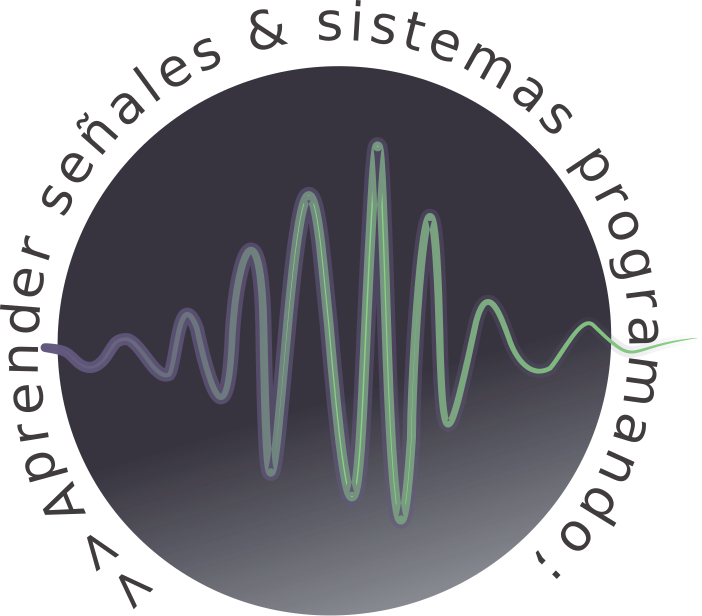

# Temario:

- Convolucion continua.

- Convolución discreta.

# Convolución continua

La convolución entre dos funciones es un concepto físico importante en muchas ramas de la ciencia. Para el caso de sistemas lineales e invariantes en el tiempo, la **integral de convolución** permite determinar la respuesta del sistema ante cualquier entrada, a partir del conocimiento de la respuesta del sistema ante una única entrada particular: **el impulso **$\delta(t)$. Si la **respuesta impulsiva **se denota como $h(t)$, la salida de un sistema LTI excitado con una entrada cualquiera $x(t)$está dada por la expresión (para sistemas no causales):


$$y(t)=x(t)*h(t)=\int_{-\infty}^{\infty}{x(\tau)h(t-\tau) d\tau}$$


Esta integral se conoce como **integral de convolución o integral de superposicion **y es la representación de una sistema continuo en el tiempo lineal e invariante en función de su respuesta impulsiva $h(t)$.

Consideremos un sistema de **tiempo continuo lineal invariante en el tiempo y causal**:


$$x(t)=\begin{cases} e^t \text{ , para } 0\leq t<1  \\  
e^{2-t} \text{ , para } 1\leq t<2 \\
0 \text{ , caso contrario } 

\end{cases}$$



$$h(t)=\begin{cases} e^{-t}\text{ , para } 0\leq t\leq4  \\  
0 \text{ , caso contrario } 

\end{cases}$$
 

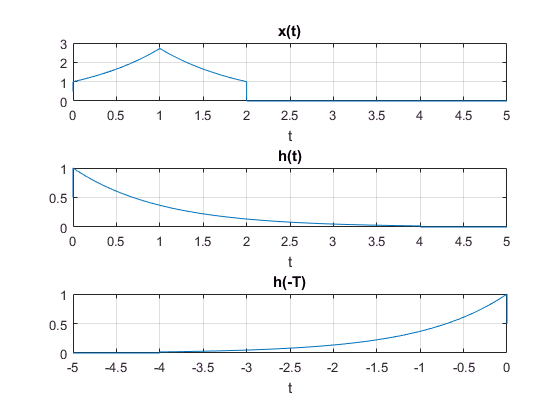

syms  t T y % T es tau
x = (heaviside(t)-heaviside(t-1))*exp(t) + ... 
    (heaviside(t-1)-heaviside(t-2))*exp(2-t);
h = (heaviside(t)-heaviside(t-4))*exp(-t);
H = (heaviside(-t)-heaviside(-t-4))*exp(t);

clf
subplot(3,1,1)
fplot(x,[0 5]); xlabel('t'); title('x(t)'); ylim([0,3]); grid on
subplot(3,1,2)
fplot(h,[0 5]); xlabel('t'); title('h(t)'); ylim([0,1]); grid on
subplot(3,1,3)
fplot(H,[-5 0]);xlabel('t'); title('h(-T)'); ylim([0,1]); grid on


$$\text{Con } 0\leq t <1 \rightarrow y(t)=x(t)*h(t)=\int_{0}^{t}{x(\tau)h(-\tau) d\tau}=\int_{0}^{t}e^\tau e^{-(t-\tau)} d\tau = 1/2 (e^t-e^{-t})$$


y = int(exp(2*T),'T',0,t);
simplify(y)

$$ans = \frac{{\mathrm{e}}^{2\,t}}{2}-\frac{1}{2}$$

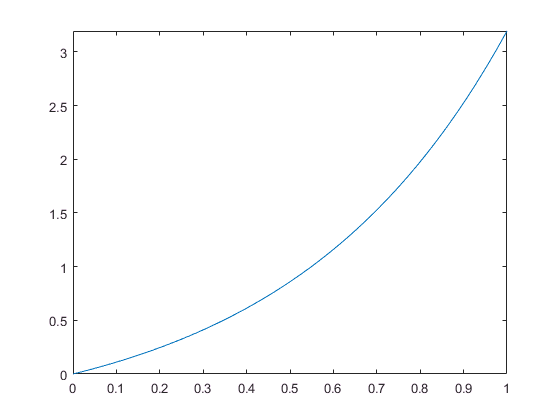

clf
fplot(y, [0 1])

# Convolución discreta

Un sistema representado en entrada/salida por lo general se expresa en términos de su respuesta al pulso unitario, la cual se define como $h[n]$. Esta respuesta es el resultado de aplicar un pulso unitario $\delta [n]$ en la entrada, es decir $x[n] = \delta [n]$. Por las propiedades de causalidad la respuesta al pulso unitario $h[n]$ debe ser cero para todos los enteros n < 0.


$$y[n] = \sum_{i=0}^{n}{h[i]x[n-i]} , n\ge 0,$$


se lo conoce como la convolución de $h[n]$ y $x[n]$, y se denota com el símbolo "$*$", por lo tanto:


$$y[n] = h[n]*x[n]=\sum_{i=0}^{n}{h[i]x[n-i]}.$$


Una consecuencia interesante de la representación de convolución es que el sistema está determinado completamente por la respuesta al pulso unitario $h[n]$. En particular, si conocemos $h[n]$, la respuesta de salida resultante de cualquier entrada $x[n]$ puede calcularse, evaluando la ultima ecuación.

Veamos un ejemplo de la convolución de un pulso unitario consigo mismo [Kamen, Edward W., 2008]:

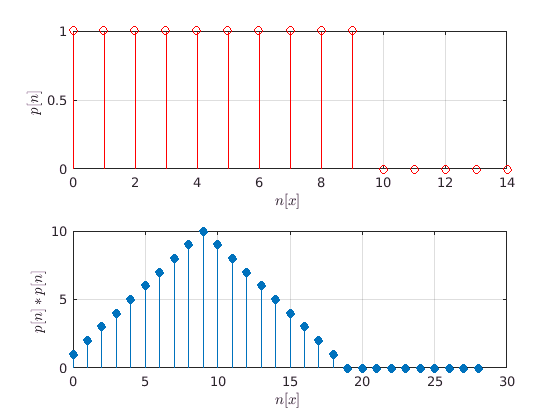

p = [ones(1,10) zeros(1,5)]; % corresponde de n = 0 a n = 14
x = p; h = p;
y = conv(x,h);
n = 0:28; 
subplot(2,1,1)
N = 0:14;
stem(N,x,'r'); xlabel('$$ n[x] $$ ','interpreter','latex'); ylabel('$$ p[n] $$ ','interpreter','latex');
grid on
subplot(2,1,2)
stem(n,y,'filled'); xlabel('$$ n[x] $$ ','interpreter','latex'); ylabel('$$ p[n]*p[n] $$ ','interpreter','latex');
grid on  

La convolución tambien la podemos ver como la multiplicación de polinomios, como en el siguiente ejemplo:


$$(x^2+1)(2x+7) = 2x^3+7x^2+2x+7$$


u = [1 0 1];
v = [2 7];
w = conv(u,v)

w =      2     7     2     7


Esta multiplicación no es posible realizarla de la siguiente forma

% w = u*v; 
% w = u.*v;

En ambos casos la loguitud del vector resultante es 

(length(u) + length(v) - 1 ) & length(w)

ans =    1



y=@(t) 1.0*(t>=0).*exp(-3*t);
x=@(t) 1.0*(t==3)-1.0*(t==5);
delta=0.0001;
tx=2:delta:6; %tx=(-200:300)*delta;
ty=-1:delta:1.5; % ty=(-100:300)*delta;
c=conv(y(ty),x(tx))*delta;
tc=(tx(1)+ty(1)):delta:(tx(end)+ty(end));
figure()
title('c')
subplot(3,1,1)
plot(tx,x(tx))
xlabel('n'); title('x(t)'); ylim([min(x(tx))-1,max(x(tx))+1]); grid on
subplot(3,1,2)
plot(ty,y(ty))
xlabel('n'); title('h(t)'); ylim([min(y(ty))-1,max(y(ty))+1]); grid on
subplot(3,1,3)
plot(tc,c);
xlabel('n'); title('x(t)*h(t)');ylim([min(c)-1,max(c)+1]); grid on

fasdf

Fs=100; % use higher sampling rate
t=-10:1/Fs:10;
d=(abs(t)-1)==0; % use kronecker delta function for discrete-time simulation
s=sign(t);
x=d.*s;
x2=1*(t>-1 & t<2);
spl=conv(x,x2,'same');

% plots to visualize the results
figure;
subplot(3,1,1);
plot(t, x2);
ylabel('f(x)');
subplot(3,1,2);
plot(t, x);
ylabel('g(x)');
subplot(3,1,3);
plot(t, spl);
xlabel('Time');
ylabel('convolution');

## Cálculo de la salida del sistema (Script_04_01)

Ahora vamos a considerar un sistema de tiempo discreto (señal digital) lineal e invariante en el tiempo y causal, por ejemplo la respuesta acustica de un recinto frente a un estimulo sonoro con:

- Señal de entrada $x[n]$.

- Respuesta al impulso del recinto $h[n]$.

- La respuesta del recinto frente al estimulo $x[n]$es igual a la convolución de tiempo discreto $h[n]*x[n]$.

Descargue del siguiente link http://www.openairlib.net/ , una respuesta al impulso y una señal anecoica. A partir de estos dos archivos diseñe un script que convoluciones dichas señales y obtener la señal como si se ejecutara en dicho recinto. Como se demostrará en futuras unidades la convolucion es costoso computacionalmente hablando, para realizar dicho procedimiento se utilizara propiedades de la Transformada de Fourier, de modo de aumentar el rendimiento en los calculos.

% script_04_01()

## Ejercicios de la guía n°3 (script_04_02)

Resolver el ejercicio n°1 con un script en MATLAB.

Ejemplo, verifique las siguientes igualdades:


$$\text{a. } x(t)*\delta(t) = x(t)$$



$$\text{b. } x(t)*\delta(t-t_0) = x(t-t_0)$$


% script_04_02()

## Ejercicios de la guía n°3 (script_04_03)

Resolver el ejercicio n°2 con un script en MATLAB.

Ejemplo,la entrada y la respuesta al impulso de un sistema continuo, lineal e invariante en el tiempo (LTI), están dadas por las siguientes expresiones:


$$x(t) = u(t)\text{;     } h(t) = e^{-\alpha t}u(t) \text{,   } \alpha >0$$


Obtenga la salida y(t), empleado

% script_04_03()

## Referencias

- Kamen, Edward W., and Bonnie S. Heck. ***Fundamentos de señales y sistemas usando la Web y Matlab***. Pearson Prentice-Hall, 2008.